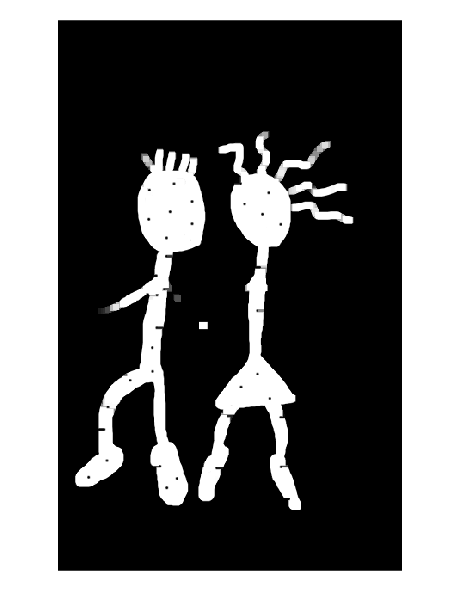

%EXERCICI 1

img = im2double(imread('Evarist.png'));
se = ones(7,7);

%apartat a
opening = imdilate(imerode(img,se),se);
imshow(opening);%Opening

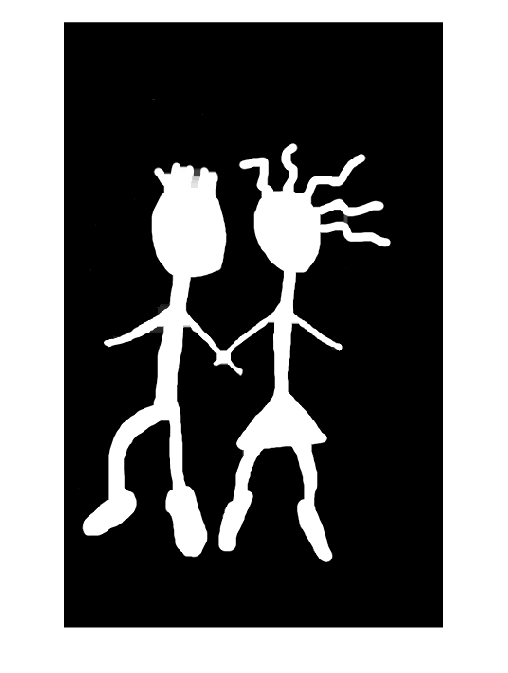


%apartat b
closing = imerode(imdilate(img,se),se);
imshow(closing);%Closing

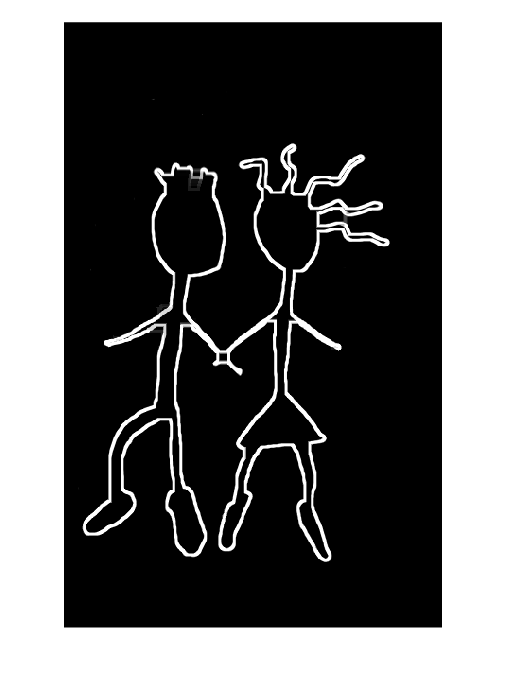


%apartat c
erosion = imerode(closing,se);
borders = closing - erosion;
imshow(borders);

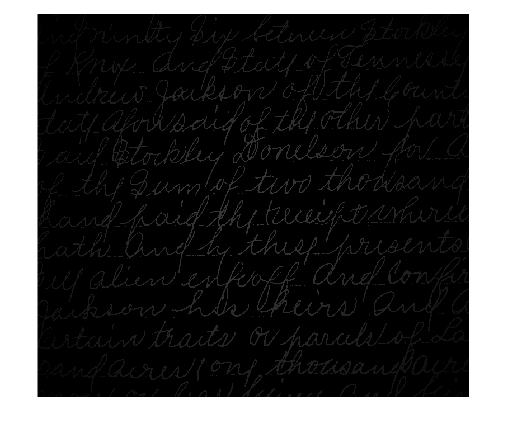



%EXERCICI 2

img = im2double(imread('letters.png'));
se = ones(7,7);

bottom_hat = imerode(imdilate(img,se),se) - img;
imshow(bottom_hat);

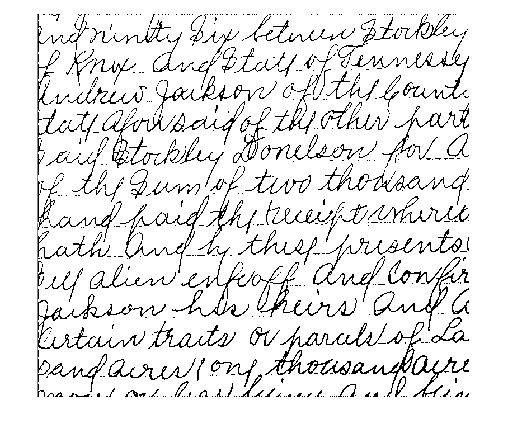


f = bottom_hat == 0;
imshow(f);